## CLEAR

clc, clear all, close all
% full parallelepiped for TUG and LLM
% height = 13.18 m
% width = 13.18 m
% length = 13.4 m

## Launch-Landing Module

% LLM Parameters
LLM.name = "Launch-Landing Module";
LLM.type = "cylinder";
LLM.color = [0.2 0.6 1]; % RGB

LLM.propellant.mass = 7500;
LLM.propellant.isp = 460;

LLM.mass.dry = 5000;
LLM.mass.wet_descent = LLM.mass.dry + LLM.propellant.mass;

LLM.size.height = 7;
LLM.cog = [0 0 LLM.size.height/2];
if LLM.type == "cylinder"
    LLM.size.radius = 4;
    LLM.area_inertia = inertia_cylinder(LLM.size.radius, LLM.size.height);
elseif LLM.type == "hollow_cylinder"
    LLM.size.radius_out = 3.8;
    LLM.size.radius_in = 1.8;
    LLM.area_inertia = inertia_hollow_cylinder(LLM.size.radius_in,LLM.size.radius_out,LLM.height);
end

% Thruster Main Engine
LLM.main_engine.Fmax = 240000;
LLM.main_engine.tau = 1.2;
LLM.main_engine.u_min = 0.1; % Minimum percentage for throttability
LLM.main_engine.gimbal_deg = 10; % max angle of gimbal
LLM.main_engine.gimbal_rad = pi/180*10;
LLM.main_engine.misallignment_alpha = 0.05; % deg
LLM.main_engine.misallignment_beta = 180; % deg
LLM.main_engine.misallignment_offset = 0.2; % deg

% Reaction Control System
LLM.rcs.Fmax = 500;
LLM.rcs.tau = 0.8;
LLM.rcs.num_thruster_per_axis = 2; % number of thrusters for each axis in one versus
LLM.rcs.isp = 350;
LLM.rcs.misallignment_alpha = 0.3; % deg
LLM.rcs.misallignment_beta = 180; % deg
LLM.rcs.misallignment_offset = 2; % deg

## Space Tug

% ST Parameters
ST.name = "Space Tug";
ST.type = "cylinder";

ST.propellant.mass = 7212;
ST.propellant.isp = LLM.propellant.isp;

ST.mass.dry = 3000;
ST.mass.wet = ST.mass.dry + ST.propellant.mass;

ST.size.radius = 2; 
ST.size.height = 8;
ST.size.offset = 4.5; % if 0, ST attach on the upper lander surface; if > 0, it will be shifted down, in the lander hole

ST.color = [1 0.5 0.2]; % RGB

ST.area_inertia = inertia_cylinder(ST.size.radius, ST.size.height);
ST.cog = [0 0 ST.size.height/2 + LLM.size.height-ST.size.offset];

## GEO Target

% GEO Sat Parameters
GEOSAT.name = "GEO Satellite";
GEOSAT.type = "box";

GEOSAT.propellant.mass = 0;

GEOSAT.mass.dry = 3000;
GEOSAT.mass.wet = GEOSAT.mass.dry + GEOSAT.propellant.mass;

GEOSAT.size.length = 4;
GEOSAT.size.width = 4;
GEOSAT.size.height = 5 ;
GEOSAT.color = [0.8 0.2 0.2];

% GEO Sat Inertia Matrix
GEOSAT.area_inertia = inertia_box(GEOSAT.size.height, GEOSAT.size.width, GEOSAT.size.length);

GEOSAT.cog = [0 0 GEOSAT.size.height/2 + LLM.size.height + ST.size.height - ST.size.offset];

## Multi-Body System in Landing Phase

%%% Multi-Body Center of Mass
llm_st_inertia_box = inertia_box(13.18,13.18,13.4)

llm_st_inertia_box =    29.4394         0         0
         0   29.4394         0
         0         0   28.9521


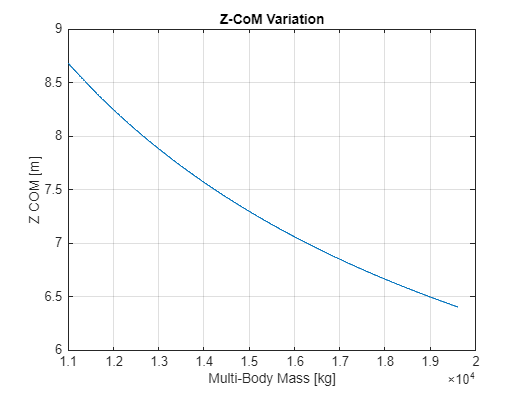


Mi = LLM.mass.wet_descent + ST.mass.dry + GEOSAT.mass.dry; % Initial mass at Landing
Mf = LLM.mass.dry + ST.mass.dry + GEOSAT.mass.dry; % Final mass after touchdown

N = 1000; % Number of points in in the plot
LLM_mass_landing = linspace(Mf,Mi,N);
COM_values = [];

for i = LLM_mass_landing
    r_com = (i*LLM.cog + ...
             ST.mass.dry*ST.cog + ...
             GEOSAT.mass.dry*GEOSAT.cog)/i;
    COM_values = [COM_values, r_com'];
end

figure
plot(LLM_mass_landing, COM_values(3,:), '-')
xlabel('Multi-Body Mass [kg]')
ylabel('Z COM [m]')
grid on
title('Z-CoM Variation')

%%% Multi-Body Total Inertia during Descent Phase

% CoM di ciascun corpo come COLONNE 3xN
centers_of_mass = [LLM.cog.' , ST.cog.' , GEOSAT.cog.'];  % 3x3, colonne = corpi

ST.mass_inertia    = ST.mass.dry    * ST.area_inertia;     % 3x3
GEOSAT.mass_inertia = GEOSAT.mass.dry * GEOSAT.area_inertia; % 3x3

Inertia_MB = zeros(3,3,numel(LLM_mass_landing));  % array 3x3xN per salvare tutte le matrici
k = 1;
for mLLM = LLM_mass_landing
    masses   = [mLLM, ST.mass.dry, GEOSAT.mass.dry];       % 1x3
    inertias = { mLLM*LLM.area_inertia , ST.mass_inertia , GEOSAT.mass_inertia }; % 1x3 cell di 3x3
    I_total  = total_inertia(masses, centers_of_mass, inertias);
    Inertia_MB(:,:,k) = I_total;
    k = k + 1;
end

% (facoltativo) verifica i fuori-diagonale nell’ultima istanza
It = Inertia_MB(:,:,end);
It = 0.5*(It+It.');  % simmetrizza
off = norm([It(1,2) It(1,3) It(2,3)]);
fprintf('||offdiag|| = %.3e\n', off);

||offdiag|| = 0.000e+00


## Plots

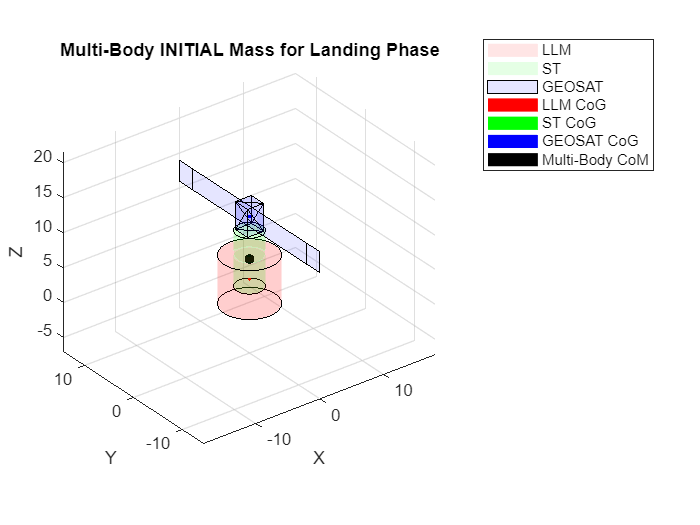

% 3D models
plot_stack(LLM.size.radius, LLM.size.height, ...
           ST.size.radius, ST.size.height, ...
           GEOSAT.size.height,GEOSAT.size.width,GEOSAT.size.length, ...
           LLM.cog,ST.cog,GEOSAT.cog, COM_values(:,1000), ST.size.offset,'Multi-Body INITIAL Mass for Landing Phase')

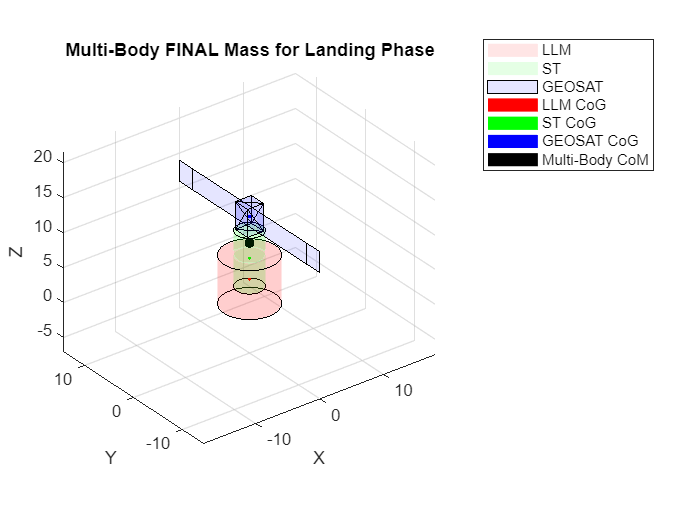

plot_stack(LLM.size.radius, LLM.size.height, ...
           ST.size.radius, ST.size.height, ...
           GEOSAT.size.height,GEOSAT.size.width,GEOSAT.size.length, ...
           LLM.cog,ST.cog,GEOSAT.cog, COM_values(:,1), ST.size.offset,'Multi-Body FINAL Mass for Landing Phase')

## RCS Torque/Force Limit due to GEO target's CoM misalignment

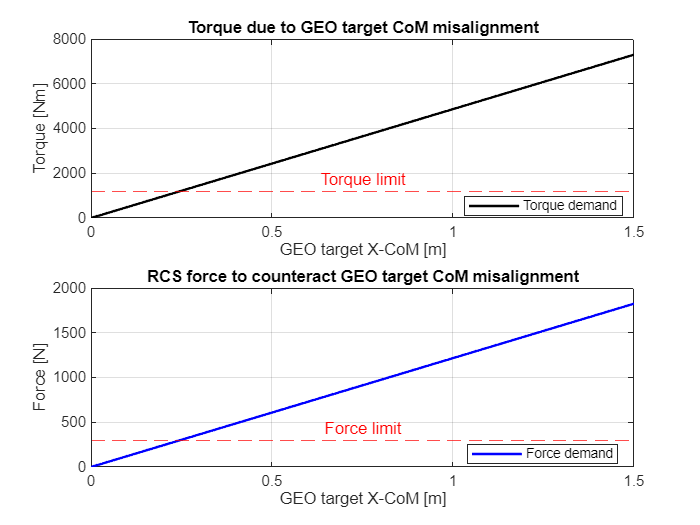

% Since ee are going to design the launch-landing module and the space tug,
% let's assume that their center of masses are going to be aligned.
% Evaluate torque to be applied by RCS in case the CoM of the GEO target
% has the CoM not aligned. Suppose it's shifted along X-axis

r = LLM.size.radius;
GEO_com = linspace(0,1.5,1000);

Torque_misallignment = GEOSAT.mass.dry * 1.622 * GEO_com;
F_rcs = Torque_misallignment / r;

% Max Torque and Force. TO BE UPDATED based on real RCS
limit_torque = 300;
limit_force = limit_torque / r;

limit_force = 300; % assuming 2 RCS activated in both directions, 500 N (more or less the force of the RCS thrusters of Altair Lander)
limit_torque = limit_force * r;

figure

% ---- Subplot 1: Torque ----
subplot(2,1,1)
plot(GEO_com, Torque_misallignment, 'k-', 'LineWidth', 1.5); hold on; grid on
yline( limit_torque, 'r--', 'Torque limit', 'LabelHorizontalAlignment','center');
title('Torque due to GEO target CoM misalignment')
xlabel('GEO target X-CoM [m]')
ylabel('Torque [Nm]')
legend('Torque demand','Location','best'); hold off

% ---- Subplot 2: Force ----
subplot(2,1,2)
plot(GEO_com, F_rcs, 'b-', 'LineWidth', 1.5); hold on; grid on
yline( limit_force, 'r--', 'Force limit', 'LabelHorizontalAlignment','center');
title('RCS force to counteract GEO target CoM misalignment')
xlabel('GEO target X-CoM [m]')
ylabel('Force [N]')
legend('Force demand','Location','best'); hold off

## Gimbal

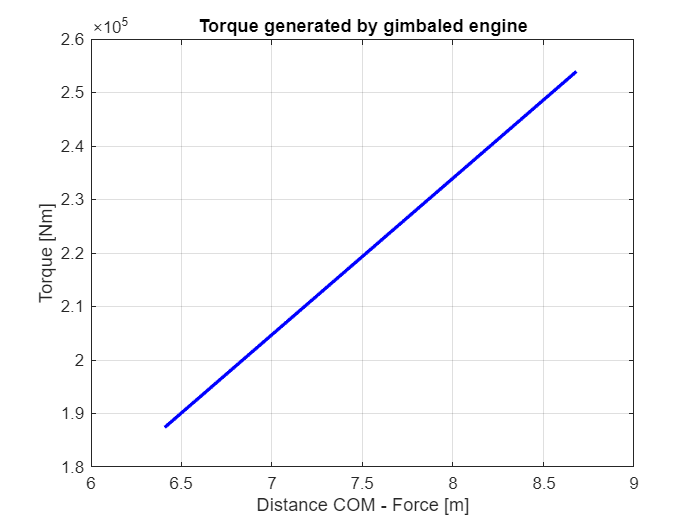

% Parameters
gimbal_angle = 7; % [deg]
Fmax = LLM.main_engine.Fmax; % Engine maximum thrust [N]

% Extract minimum and maximum values of the COM-force distance
d_F_com_min = COM_values(3,1000); 
d_F_com_max = COM_values(3,1);

% Create a range of values between min and max
d_F_com = linspace(d_F_com_min, d_F_com_max, 200);

% Compute lever arm and torque
lever = d_F_com .* sind(gimbal_angle);
T = Fmax .* lever;

% Plot
figure;
plot(d_F_com, T, 'b-', 'LineWidth', 2);
grid on;
xlabel('Distance COM - Force [m]');
ylabel('Torque [Nm]');
title('Torque generated by gimbaled engine');

## Simulation

% Parameters
g_moon = 1.62;  % m/s^2
g0 = 9.81;      % m/s^2

f_plant = 100;
f_controller = 50;
f_guidance = 1;

sigma_pos = 1;
sigma_vel = 0.015;


% Navigation
% Attitude Sensor Suite
sig_st = 3e-4;      % [rad] Star Tracker
sig_cam = 0.017;    % [rad] Camera with markers
sig_g = 5e-5;       % [rad/s/Hz] IMU
sig_bg = 1e-5;      % [rad/s/sqrt(s)] IMU
f_IMU = 100;        % [Hz] IMU frequency
Ts = 0.01;
Q = 7;
R = 0.05;

mass_err_perc = 5;

%% RCS Model
km = 4.25;
tau = 0.8;
Uon = 0.3;
Uoff = 0.1;
min_on = 0.05;
min_off = 0.1;
dwell_param = [Uon; Uoff; min_on; min_off];
db = 0*[-100 100];
db_omega = 0.05*pi/180;

% Initial state
% initial position and velocity
x0  = 289448.1899567346;        % initial downrange to target (m)
z0  = 15e3; 
y0  = 0e3; 
vx0 = -1695;                    % horizontal speed toward target (m/s) (negative if x decreases)
vz0 = 0;  
vy0 = 0 ;                       % vertical descending speed (m/s, negative downward)
r0 = [x0; y0; z0];
v0 = [vx0; vy0; vz0];

% GUIDANCE LAW
% Breaking phase
    x1_t  = 25000;    y1_t = 0;    z1_t  = 7936.75104830166;  % position targets at end of phase 1
    vx1_t = -202;     vy1_t = 0;   vz1_t = -49.09;            % velocity targets at end of phase 1
    Tgo1  = max(10, (x1_t - x0) / (0.5*(vx0 + vx1_t)));
    tgo_breaking  = Tgo1 + 5;   % add a few seconds buffer to ease transitions (if needed)
    rt_breaking = [x1_t; y1_t; z1_t];
    vt_breaking = [vx1_t; vy1_t; vz1_t];
    target_breaking = [rt_breaking vt_breaking];
% Approach phase
    x2_t   = 0;      y2_t = 0;     z2_t   = 100;              % position targets at end of phase 2
    vx2_t  = 0;      vy2_t = 0;    vz2_t  = -8;               % velocity targets entering vertical phase
    ax2_t  = 0;      ay2_t = 0;    az2_t  = 1.2*g_moon;       % target acceleration at end of phase 2 (hover ~1.2 g)
    Tgo2  = max(10, (x2_t - x1_t) / (0.5*(vx1_t + vx2_t)));
    tgo_approach  = Tgo2 + 5;   % add a few seconds buffer to smooth approach phase
    rt_approach = [x2_t; y2_t; z2_t];
    vt_approach = [vx2_t; vy2_t; vz2_t];
    at_approach = [ax2_t; ay2_t; az2_t];
    target_approach = [rt_approach vt_approach at_approach];
% Vertical descent
    az3_t = 1.2*g_moon;     % target vertical thrust accel in final phase (~1.2 g_moon)
    vx_tol_touch = 0.5;     % horizontal velocity tolerance at touchdown (m/s)
    vy_tol_touch = 0.5;     % horizontal velocity tolerance at touchdown (m/s)
    vz3_t = -1.0;           % target touchdown vertical speed (m/s ~ -1)
    target_vdesc = [vx_tol_touch; vy_tol_touch; vz3_t; az3_t];
    f_cut = 0.5;

% CONTROL LAW
% Control Parameters
kr = 6*[0.5 0.5 0.8]';
ka = 0.2*kr;

% Initial attitude
c0 = (-2*(vt_breaking+2*v0))/tgo_breaking + 6*(rt_breaking - r0)/(tgo_breaking^2);
eul0 = force2eul(c0);
q0 = eul2quat(eul0);

%% ====== Funzioni di supporto (nello stesso file va benissimo) ======
function draw_axis(o, dir, L, c, labeltxt)
    dir = dir / norm(dir);
    v = dir * L;
    quiver3(o(1), o(2), o(3), v(1), v(2), v(3), 0, ...
        'LineWidth', 2, 'MaxHeadSize', 0.5, 'Color', c);
    text(o(1)+1.05*v(1), o(2)+1.05*v(2), o(3)+1.05*v(3), ['  ' labeltxt], ...
        'FontWeight','bold', 'Color', c);
end

function R = dcm_from_quat(q) % q = [w x y z]
    q = q(:).'/norm(q);
    w=q(1); x=q(2); y=q(3); z=q(4);
    R = [1-2*(y^2+z^2),   2*(x*y - z*w), 2*(x*z + y*w);
         2*(x*y + z*w), 1-2*(x^2+z^2),   2*(y*z - x*w);
         2*(x*z - y*w),   2*(y*z + x*w), 1-2*(x^2+y^2)];
end

function R = dcm_from_euler321(yaw, pitch, roll) % Z-Y-X
    cy=cos(yaw);  sy=sin(yaw);
    cp=cos(pitch);sp=sin(pitch);
    cr=cos(roll); sr=sin(roll);
    Rz = [cy -sy 0; sy cy 0; 0 0 1];
    Ry = [cp 0 sp; 0 1 0; -sp 0 cp];
    Rx = [1 0 0; 0 cr -sr; 0 sr cr];
    R = Rz*Ry*Rx;
end

function R = in2body(f)  
    R1 = @(bank)  [cos(bank) sin(bank) 0; -sin(bank) cos(bank) 0; 0 0 1];
    R2 = @(pitch) [sin(pitch) 0 -cos(pitch); 0 1 0; cos(pitch) 0 sin(pitch)];
    bank = atan2(f(2,:),f(1,:));
    f_rot = R1(bank)*f;
    pitch = atan2(f_rot(3,:),f_rot(1,:));
    R = R2(pitch)*R1(bank);
end


function eul = force2eul(f)
    R1 = @(bank)  [cos(bank) sin(bank) 0; -sin(bank) cos(bank) 0; 0 0 1];
    R2 = @(pitch) [sin(pitch) 0 -cos(pitch); 0 1 0; cos(pitch) 0 sin(pitch)];
    bank = atan2(f(2,:),f(1,:));
    F_cmd_rot = R1(bank)*f;
    pitch = atan2(F_cmd_rot(3,:),F_cmd_rot(1,:));
    R = R2(pitch)*R1(bank);
    eul = rotm2eul(R,'ZYX');
    eulx = eul(3); eulz = eul(1);
    eul(1) = eulx; eul(3) = eulz;
    eul = wrapToPi(eul);
end


flag = 0;

if flag == 1


%% PARAM SWEEP su LLM.rcs.Fmax e plot di out.pos / out.vel
close all
%% --- Prima del loop ---
Fmax_values = 350:50:700;
n = numel(Fmax_values);

final_pos     = zeros(n,3);
final_vel     = zeros(n,3);
final_eul_ang = zeros(n,3);   % [Psi Theta Phi] per riga
final_prop    = zeros(n,1);
final_propRCS = zeros(n,1);

for k = 1:numel(Fmax_values)
    F = Fmax_values(k);

    % Aggiorna il parametro per questa iterazione
    LLM.rcs.Fmax = F;

    % Esegui la simulazione
    simOut = sim('simulation.slx', 'ReturnWorkspaceOutputs', 'on');

    % Recupera dati
    time = simOut.tout;
    pos  = simOut.pos;   % [Nx3]
    vel  = simOut.vel;   % [Nx3]
    quat = reshape(simOut.quat, 4, []);
    quat_ref = reshape(simOut.quat_ref, 4, []);
    mass_ME = simOut.prop_main;
    mass_RCS = simOut.prop_rcs;
    eul_ang = reshape(simOut.eul_ang, 3, []);

    % ================= PLOT SIMULAZIONE =================
    % --- POS ---
    figure;
    subplot(2,1,1); hold on;
    plot(time, pos(:,1), 'r-');
    plot(time, pos(:,2), 'g-');
    plot(time, pos(:,3), 'b-');
    grid on;
    title(sprintf('Simulation with RCS Force Max: %d N (Position)', F));
    legend('Position X','Position Y','Position Z','Location','best');
    xlabel('Time [s]');
    ylabel('Position in inertial frame [m]');
    hold off;

    % --- VEL ---
    subplot(2,1,2); hold on;
    plot(time, vel(:,1), 'r-');
    plot(time, vel(:,2), 'g-');
    plot(time, vel(:,3), 'b-');
    grid on;
    title(sprintf('Simulation with RCS Force Max: %d N (Velocity)', F));
    legend('Velocity X','Velocity Y','Velocity Z','Location','best');
    xlabel('Time [s]');
    ylabel('Velocity in inertial frame [m/s]');
    hold off;

    % --- QUAT ---
    figure; hold on;
    plot(time, quat(1,:), 'r-');
    plot(time, quat(2,:), 'g-');
    plot(time, quat(3,:), 'b-');
    plot(time, quat(4,:), 'k-');
    plot(time, quat_ref(1,:), 'r--');
    plot(time, quat_ref(2,:), 'g--');
    plot(time, quat_ref(3,:), 'b--');
    plot(time, quat_ref(4,:), 'k--');
    title(sprintf('Simulation with RCS Force Max: %d N (Quaternion)', F));
    legend('q0','q1','q2','q3','q0 ref','q1 ref','q2 ref','q3 ref','Location','best');
    xlabel('Time [s]');
    ylabel('Quaternion');
    hold off;

      % --- PROPELLANTS ---
      figure; grid on
      plot(time,mass_ME(:,1),'k-')
      title('Propellant profile burnt by main engine')
      xlabel('Time [s]');
      ylabel('Propellant Mass [kg]');
      figure; grid on
      plot(time,mass_RCS(:,1),'r-')
      title('Propellant profile burnt by RCS')
      xlabel('Time [s]');
      ylabel('Propellant Mass [kg]');


    % ================= SALVA RISULTATI FINALI =================
    final_pos(k,:) = pos(end,:);  
    final_pos(k,3) = 0;                         % forza Z = 0, se ti serve
    final_vel(k,:) = vel(end,:);
    final_eul_ang(k,:) = eul_ang(:,end).';      % trasposto: 1x3
    final_prop(k)    = mass_ME(end);            % se è vettore colonna
    final_propRCS(k) = mass_RCS(end);           % idem

    fprintf('Iteration with F = %d N\n', F);
end


% ================= CREA TABELLA A FINE LOOP =================
results = table( ...
    Fmax_values(:), ...
    final_pos(:,1), final_pos(:,2), final_pos(:,3), ...
    final_vel(:,1), final_vel(:,2), final_vel(:,3), ...
    final_eul_ang(:,1), final_eul_ang(:,2), final_eul_ang(:,3), ...
    final_prop, final_propRCS, ...
    'VariableNames', {'Fmax_N','PosX_m','PosY_m','PosZ_m', ...
                      'VelX_ms','VelY_ms','VelZ_ms', ...
                      'Psi_deg','Theta_deg','Phi_deg', ...
                      'PropME_kg','PropRCS_kg'} );

disp('=== Risultati finali ===');
disp(results);
end